# Project

% Given system parameters
fc = 62.64e9;        % Center frequency in Hz
fs = 2e9;            % Sampling frequency in Hz
Tc = 15.2e-6;        % Chirp duration in seconds
guard_time = 0.1e-6; % Guard time at the end of each chirp

% Parameters for chirp generation
num_chirps = 256;
total_bits = 13;

% Information bits
bits_bandwidth = 7;
bits_frequency = 6;

% Generate random bit sequences for bandwidth and frequency
bandwidth_bits = randi([0, 1], num_chirps, bits_bandwidth)

bandwidth_bits =      1     1     0     0     1     1     0
     0     1     1     0     1     1     0
     0     0     0     0     0     1     1
     1     1     0     0     1     0     0
     1     0     0     0     0     1     0
     0     0     0     1     0     1     1
     0     0     1     1     0     0     0
     1     1     0     0     0     0     1
     1     0     0     0     1     1     1
     0     0     1     0     0     0     1


frequency_bits = randi([0, 1], num_chirps, bits_frequency)

frequency_bits =      1     1     1     1     0     0
     1     1     0     1     1     1
     1     0     0     0     0     0
     1     0     1     0     0     0
     1     0     0     0     0     0
     1     1     0     1     1     0
     0     0     1     1     0     1
     1     0     1     0     0     0
     0     0     0     0     0     0
     0     1     0     1     0     1


totalSignalBits = cat(2,bandwidth_bits,frequency_bits)

totalSignalBits =      1     1     0     0     1     1     0     1     1     1     1     0     0
     0     1     1     0     1     1     0     1     1     0     1     1     1
     0     0     0     0     0     1     1     1     0     0     0     0     0
     1     1     0     0     1     0     0     1     0     1     0     0     0
     1     0     0     0     0     1     0     1     0     0     0     0     0
     0     0     0     1     0     1     1     1     1     0     1     1     0
     0     0     1     1     0     0     0     0     0     1     1     0     1
     1     1     0     0     0     0     1     1     0     1     0     0     0
     1     0     0     0     1     1     1     0     0     0     0     0     0
     0     0     1     0     0     0     1     0     1     0     1     0     1


% Convert binary bits to decimal values
bandwidth_values = linspace(400e6, 800e6, 2^bits_bandwidth);
frequency_values = linspace(-100e6, 100e6, 2^bits_frequency);
selected_bandwidths = bandwidth_values(bi2de(bandwidth_bits,'left-msb') + 1);
selected_frequencies = frequency_values(bi2de(frequency_bits,'left-msb') + 1);

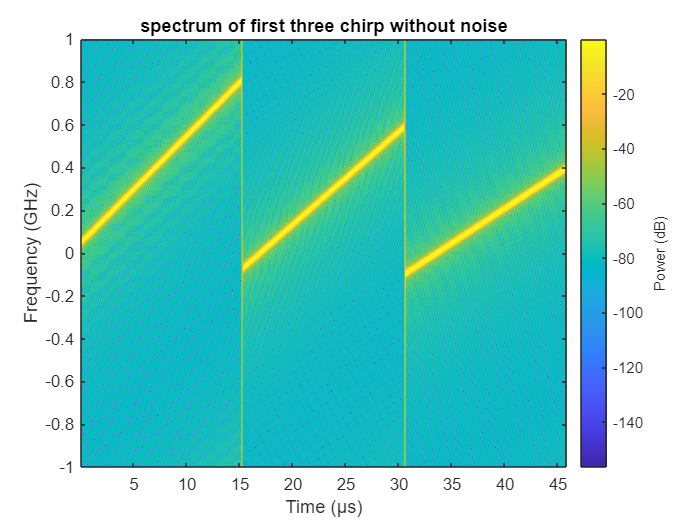

close all ;
% Generate chirps
chirp_duration = Tc + guard_time;
t = linspace(0, Tc, fs * Tc);
time = linspace(0, chirp_duration, fs * chirp_duration);
transmitted_chirps = zeros(num_chirps, fs * chirp_duration);
stepUp_chirps = zeros(num_chirps, fs * chirp_duration);

for i = 1:num_chirps
    f0 = selected_frequencies(i);
    f1 = f0 + selected_bandwidths(i);
    transmitted_chirps(i, 1:length(t)) = chirp(t,f0,Tc,f1,"linear",0,'complex');
    %%stepUp_chirps(i, :) = transmitted_chirps(i, :) .* exp(1i * 2 * pi * fc * time );
end

%%transmitted_chirps_fromAntenna = reshape(conj(stepUp_chirps'), 1, []);
transmitted_chirps_fromAntenna = reshape(conj(transmitted_chirps'), 1, []);

transmitted_chirps_beforStepup = reshape(conj(transmitted_chirps'), 1, []);

pspectrum(transmitted_chirps_beforStepup(1,1:91800),fs,'spectrogram' ...
    ,'TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
title('spectrum of first three chirp without noise')

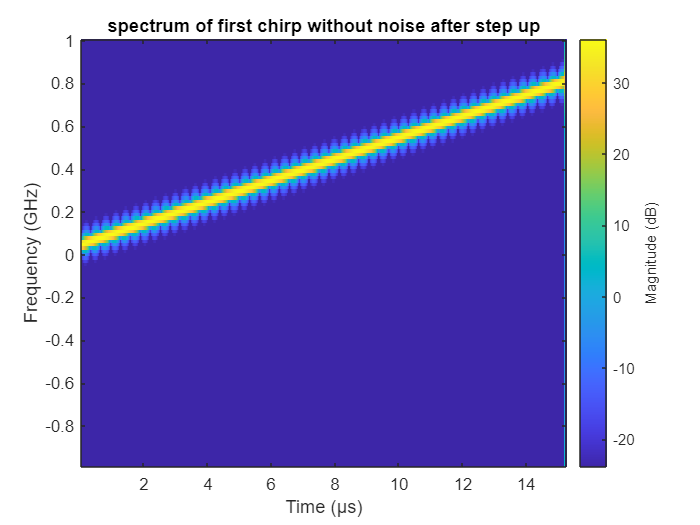

% Parameters for AWGN channel
received_chirps = zeros(3 , num_chirps*fs*chirp_duration);

received_chirps(1 , :) = awgn(transmitted_chirps_fromAntenna, -60, 'measured');
received_chirps(2 , :) = awgn(transmitted_chirps_fromAntenna, 10, 'measured');
received_chirps(3 , :) = awgn(transmitted_chirps_fromAntenna, 20, 'measured');
figure
stft(transmitted_chirps_fromAntenna(1,1:30600),fs)
title(['spectrum of first chirp without noise' ...
    ' after step up'])

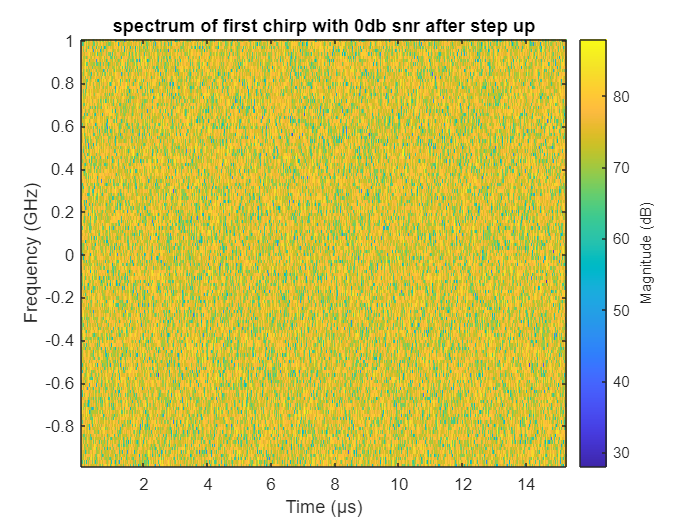

figure
stft(received_chirps(1,1:30600),fs)
title('spectrum of first chirp with 0db snr after step up')

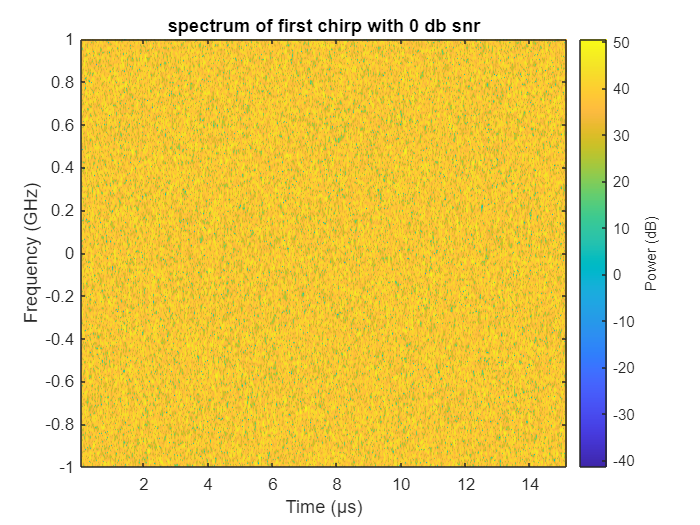

% Receiver

received_chirps_fromAntenna0dB = received_chirps(1,:) ; 
received_chirps_fromAntenna10dB = received_chirps(2,:) ;
received_chirps_fromAntenna20dB = received_chirps(3,:) ;

demoultiplaxed_signal0db = reshape(received_chirps_fromAntenna0dB,fs*Tc+200,[]);
removed_gards0db = demoultiplaxed_signal0db(1:fs*Tc, :);

demoultiplaxed_signal10db = reshape(received_chirps_fromAntenna10dB,fs*Tc+200,[]);
removed_gards10db = demoultiplaxed_signal10db(1:fs*Tc, :);

demoultiplaxed_signal20db = reshape(received_chirps_fromAntenna20dB,fs*Tc+200,[]);
removed_gards20db = demoultiplaxed_signal20db(1:fs*Tc, :);

signal0db = zeros(256,30400);
signal10db = zeros(256,30400);
signal20db = zeros(256,30400);

for i=1:256
%     signal0db(i,:) = conj(removed_gards0db(:,i)')  .* exp(-1i * 2 * pi * fc * t);
%     signal10db(i,:) = conj(removed_gards10db(:,i)')  .* exp(-1i * 2 * pi * fc * t);
%     signal20db(i,:) = conj(removed_gards20db(:,i)')  .* exp(-1i * 2 * pi * fc * t);
    signal0db(i,:) = conj(removed_gards0db(:,i)');
    signal10db(i,:) = conj(removed_gards10db(:,i)');
    signal20db(i,:) = conj(removed_gards20db(:,i)');
end

figure
pspectrum(signal0db(1,:),fs,'spectrogram' ...
    ,'TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
title('spectrum of first chirp with 0 db snr')

output0db = receiver(signal0db,pure_chirps,1)

output0db =      1     0     1     0     1     1     1     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


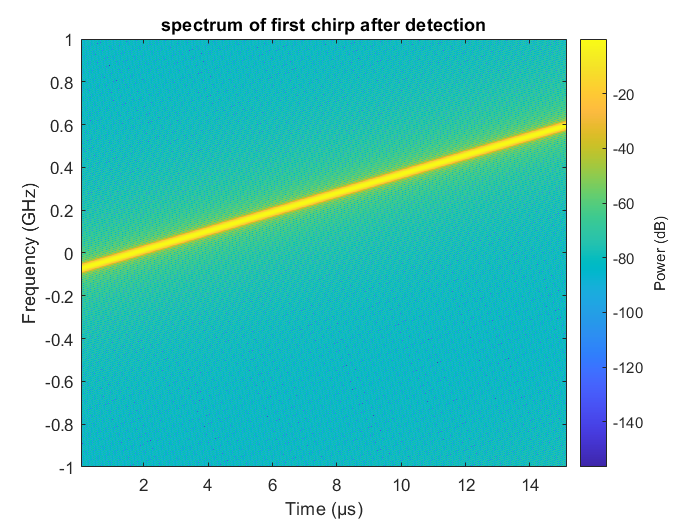

figure
pspectrum(pure_chirps(bit2int(output0db(1,:)',13,true)+1,:),fs,'spectrogram' ...
    ,'TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
title('spectrum of first chirp after detection')

% output10db = receiver(received_chirps_fromAntenna10dB,pure_chirps,5)
% output20db = receiver(received_chirps_fromAntenna20dB,pure_chirps,5)

## Practical test

load('FMCW_fcBWmod_JRC.mat');

comm_rx_data = double(data_16bit_IP)+1i*double(data_16bit_QP);
comm_rx_data = interp(comm_rx_data,2);

samplesMat = (0:255).'*30600+(1:30400);
samplesVec = reshape(samplesMat.',1,256*30400);
rx_data = comm_rx_data(samplesVec);

demoultiplaxed_signal = reshape(rx_data,fs*Tc,[]);

output_practical = receiver(conj(demoultiplaxed_signal'),pure_chirps,32)

output_practical =      0     0     1     1     1     1     0     0     1     1     1     1     0
     1     1     1     0     1     0     0     1     0     0     0     0     0
     1     1     0     0     0     1     0     1     1     1     0     1     1
     1     0     0     0     1     1     0     1     1     1     1     1     1
     0     0     0     0     1     1     1     0     0     0     0     1     1
     0     0     0     0     1     1     1     1     1     0     1     1     1
     0     0     1     0     1     0     0     1     1     1     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     1     0     1     1     1     1     0     0     1     1
     0     0     1     0     1     1     0     1     1     0     0     1     0


### plots of practical test

we analyze the initialchirp , discerning its first 7 bits for bandwidth and the remaining 6 bits for frequency , represented as binary numbers **0011110** and **011110** and decimal numbers **30** and **30**. this reveals that our initial chirp has a bandwidth of **494.49MHz,** and a initial frequency of **-4.7619MHz**.

And we identify thirty chirp binary numbers representing bandwidth and frequency denoted as **0000000** and **000000** with corresponding decimal values **0** and **0**. Consequently, the resulting chirp exhibits bandwidth and frequency characteristics designated as **400MHz** and **-100MHz**.

close all;
output_practical(1,:)

ans =      0     0     1     1     1     1     0     0     1     1     1     1     0


bandwidth = bandwidth_values(bit2int(output_practical(1,1:7)',7,true)+1)

bandwidth = 4.9449e+08

frequency = frequency_values(bit2int(output_practical(1,8:13)',6,true)+1)

frequency = -4.7619e+06

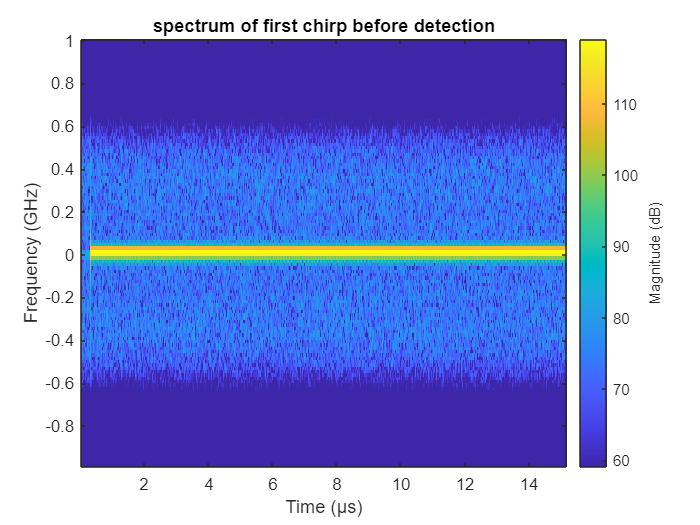

figure
%pspectrum(conj(demoultiplaxed_signal(:,1)'),fs,'spectrogram' ,'TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
stft(conj(demoultiplaxed_signal(:,1)'),fs)
title('spectrum of first chirp before detection')

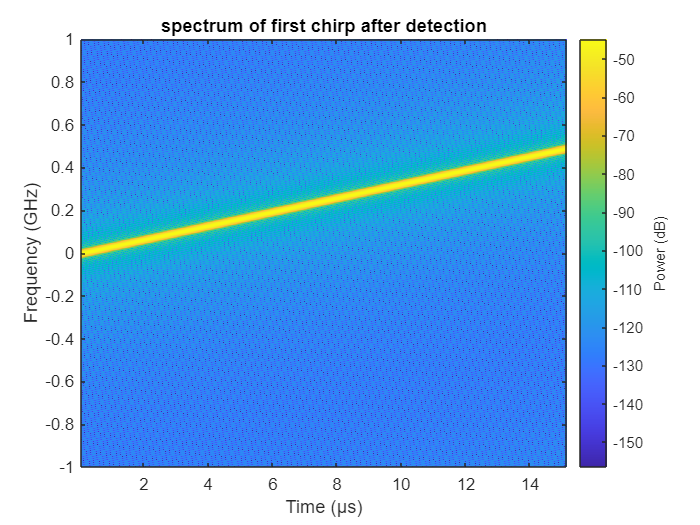

figure
pspectrum(pure_chirps(bit2int(output_practical(1,:)',13,true)+1,:),fs,'spectrogram' ...
    ,'TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
title('spectrum of first chirp after detection')

output_practical(31,:)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0


bandwidth = bandwidth_values(bit2int(output_practical(31,1:7)',7,true)+1)

bandwidth = 400000000

frequency = frequency_values(bit2int(output_practical(31,8:13)',6,true)+1)

frequency = -100000000

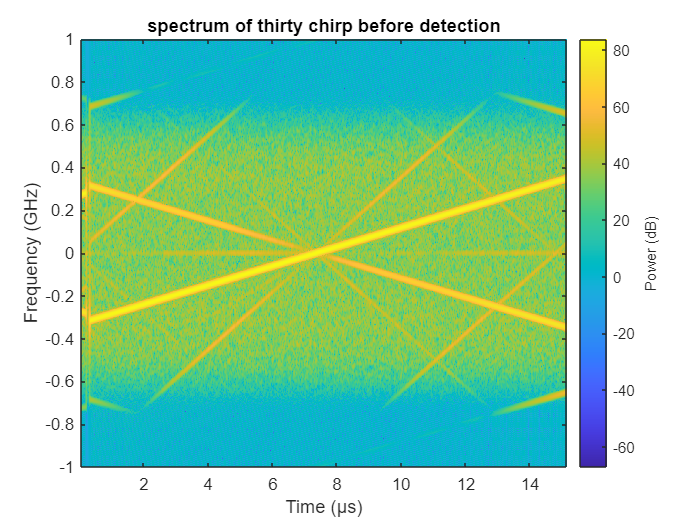

figure
pspectrum(conj(demoultiplaxed_signal(:,31)'),fs,'spectrogram' ...
    ,'TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
title('spectrum of thirty chirp before detection')

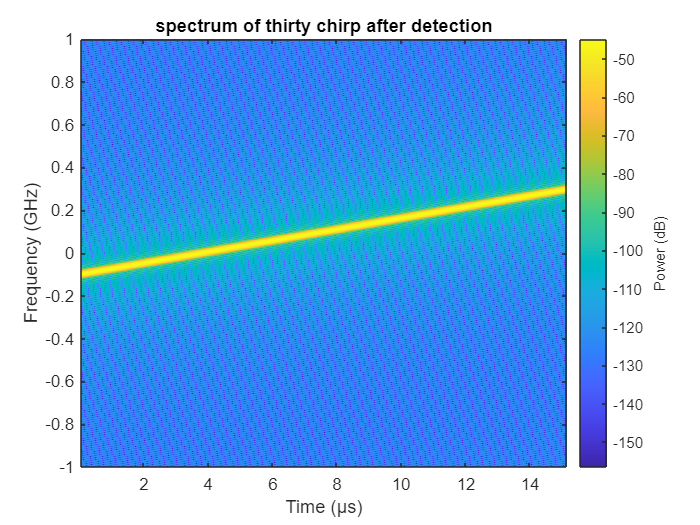

figure
pspectrum(pure_chirps(bit2int(output_practical(31,:)',13,true)+1,:),fs,'spectrogram','TimeResolution',1e-7, 'OverlapPercent',99,'Leakage',0.85)
title('spectrum of thirty chirp after detection')

## functions

function out = receiver(signal,refrence,number_chirps_to_detect)

    out = zeros(256, 13);
    
    for i= 1:number_chirps_to_detect
        temp = signal(i,:)/norm(signal(i,:));
        out(i,:) = ml_section(temp,refrence);
    end

end




function out = ml_section(signal,refrence)

    distance = zeros(1,8192);
    
    for i = 1:8192
         distance(1,i) = abs(norm(refrence(i,:) - signal));
    end

    [~ , minIndex] = min(distance);
    out = int2bit(minIndex-1,13,true)';

end
